## MT3005 - Clase 6

Para el ejemplo del manipulador serial RR

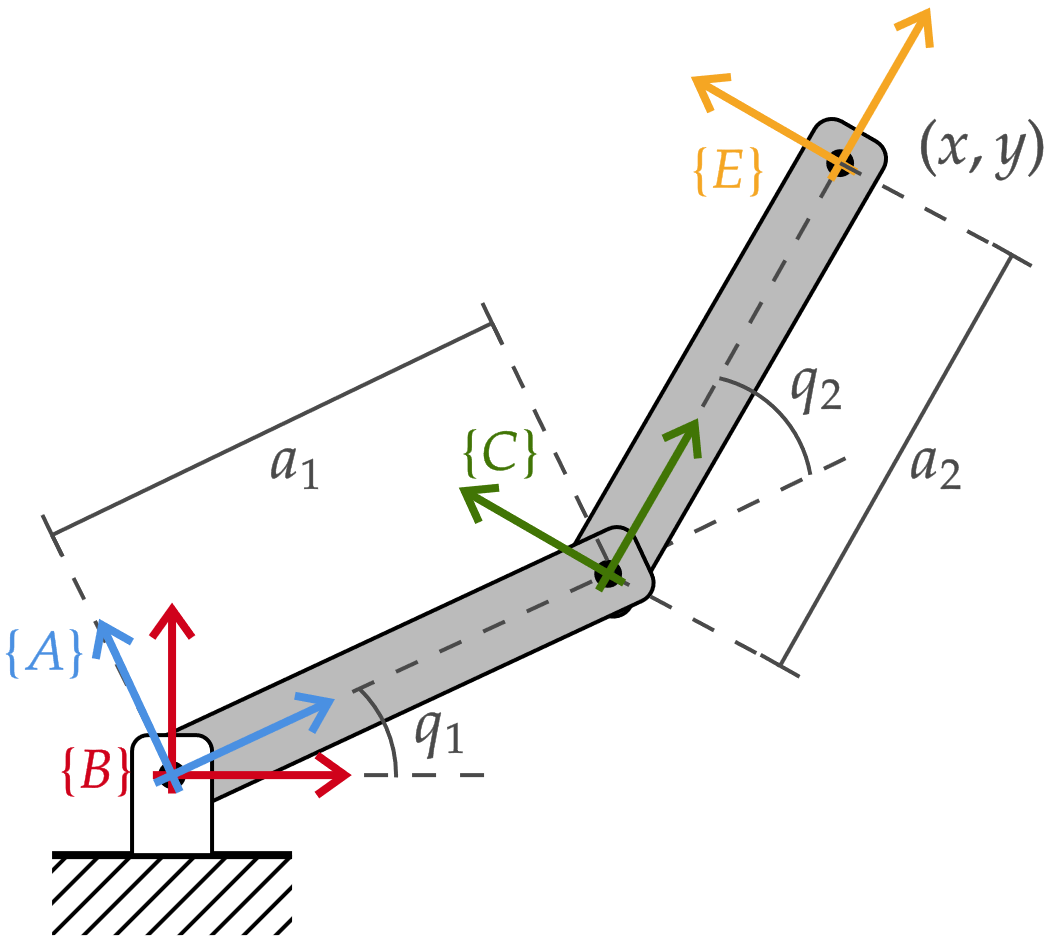

calcularemos la cinemática diferencial tanto "a mano" empleando la Toolbox de matemática simbólica como la Robotics Toolbox. Para el primer caso, definimos la cinemática directa del manipulador y extraemos la posición del efector final:

% Parámetros del robot
a1 = 1;
a2 = 1;
syms q1 q2

% Definimos la cinemática directa del manipulador
K(q1, q2) = simplify(trot2(q1)*transl2(a1,0)*trot2(q2)*transl2(a2,0))

$$K(q1, q2) = \left(\begin{array}{ccc} \cos\left(q_{1}+q_{2}\right) & -\sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right) & \cos\left(q_{1}+q_{2}\right) & \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right)\\ 0 & 0 & 1 \end{array}\right)$$

BT_E = simplify(trot2(q1)*transl2(a1,0)*trot2(q2)*transl2(a2,0));

% Extraemos la posición del efector final en función a la configuración
p(q1, q2) = BT_E(1:2,3)

$$p(q1, q2) = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right) \end{array}\right)$$

Ya con la expresión simbólica para la posición de efector pasamos a emplear la función jacobian para obtener el jacobiano de velocidad lineal del manipulador

% Determinamos el jacobiano
Jv(q1, q2) = jacobian(p(q1, q2), [q1, q2])

$$Jv(q1, q2) = \left(\begin{array}{cc} -\sin\left(q_{1}+q_{2}\right)-\sin\left(q_{1}\right) & -\sin\left(q_{1}+q_{2}\right)\\ \cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right) & \cos\left(q_{1}+q_{2}\right) \end{array}\right)$$


% Podemos emplear una configuración de prueba...
cfg = [pi/6, pi/3];

% ...como verificación
double(Jv(cfg(1), cfg(2)))

ans =    -1.5000   -1.0000
    0.8660         0


Para el caso de la Robotics Toolbox, basta con definir de nuevo el robot mediante un objeto SerialLink y obtener directamente el jacobiano con respecto de la base:

J1 = Revolute('a',a1);
J2 = Revolute('a',a2);

planRR = SerialLink([J1, J2], 'name', 'planRR')

 
planRR = 
 
planRR:: 2 axis, RR, stdDH, slowRNE                              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          1|          0|          0|
|  2|         q2|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



planRR.jacob0(cfg)

ans =    -1.5000   -1.0000
    0.8660    0.0000
         0         0
         0         0
         0         0
    1.0000    1.0000


Nótese que la Robotics Toolbox otorga el jacobiano completo y no sólo el de velocidad lineal (o posición).

¿Qué pasa si quisiéramos calcular el jacobiano de velocidad angular del manipulador de forma analítica?

% Definimos la configuración como funciones de tiempo genéricas
syms q1(t) q2(t) dq1 dq2

% Definimos la orientación del efector final
ER_B = [cos(q1+q2),-sin(q1+q2);sin(q1+q2),cos(q1+q2)]

$$ER\_B(t) = \left(\begin{array}{cc} \cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & -\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ \sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & \cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$


% Diferenciamos con respecto al tiempo
dER_B = diff(ER_B, t)

$$dER\_B(t) = \begin{array}{l} \left(\begin{array}{cc} \sigma_{1} & -\sigma_{2}\\ \sigma_{2} & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)\\ \sigma_{2}=\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right) \end{array}$$


% Encontramos la matriz antisimétrica
SS = simplify(dER_B*ER_B.')

$$SS(t) = \left(\begin{array}{cc} 0 & -\frac{\partial }{\partial t}q_{1}\left(t\right)-\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right) & 0 \end{array}\right)$$


% Extraemos la velocidad angular desde la matriz antisimétrica y
% sustituimos las derivadas del toolbox con nuevas variables simbólicas
S = SS(t);
omega = subs(S(2,1), {diff(q1(t), t), diff(q2(t), t)}, [dq1, dq2])

$$omega = {\mathrm{dq}}_{1}+{\mathrm{dq}}_{2}$$

Este procedimiento se simplificará de forma numérica en el **Laboratorio 6**.